# Prognostic Health Management

**Name**: 

Kwak, Jin/21900031

Kim, Sunwoo/22000090

**Date**       :2024.10.05

**Modified**:2024.10.12

# Introduction

In this lab, [](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)[AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM) is used to develop a machine learning model for coil defect diagnosis(Hot-Air Process Equipment)

### **Process Description**

Hot-Air Drying Process:

    - Ensures that the film and protective agents adhere stably to the metal surface after plating

    - Completely dries moisture from the product surface.

    - Used in various fields(e.g. electronic component coating, automotive paint processes, and ceramic processes)

    - **Process Defects**

        - High power consumption using coil $\rightarrow$Overheating, Irregular temperature transmission $\rightarrow$Poor product quality/Equipment Fault

        - Coil fault may cause issues with the cooling motor $\rightarrow$ Vibration patterns changes.

The goal is to identify these changes to diagnose the issues early on and prevent equipment failure.

## Goal of the Project

Two separate, distinguishable goals.

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish degradation model

## Specific Goals

1.1) Achieve detection(Normal/Error) accuracy up to 90% 

1.2) Ensure the model performance with Feature Reduction and analyze the feature reduction

2.1) 80% < Probability of Predicted RUL within αbound after Train-Test Breakpoint

## Dataset

Dataset name: [AI dataset for early detection of equipment abnormalities](https://www.kamp-ai.kr/aidataDetail?AI_SEARCH=&page=1&DATASET_SEQ=23&EQUIP_SEL=&GUBUN_SEL=C004025&FILE_TYPE_SEL=&WDATE_SEL=CLICK_NUM)

Data Measurement:

- PLC data(Sampling Period: 5[sec])

- Sound data

Data Categories:

- Numerical data from PLC 

- Sound data:

- Error Lot list

## **Goal of the Project**

Two main goals of the project are introduced in this project. The dataset is originally used for classification. Authors will prepare for a **ML model for fault classification** and **Fault Diagnosis Model(Remaining Useful Life Estimation Model)**

- Development of a Machine Learning model for coil defect diagnosis using data in Hot-Air process equipment

- Analysis of the Remaining Useful Life trend and establish **degradation model**

## **Expected Outcome**

**Before: **Difficulty on immediate problem check of coil defects on-site on real-time base

**After: **Quickly respond to equipment fault $\rightarrow$Equipment management, Increase in productivity.

## Schedule

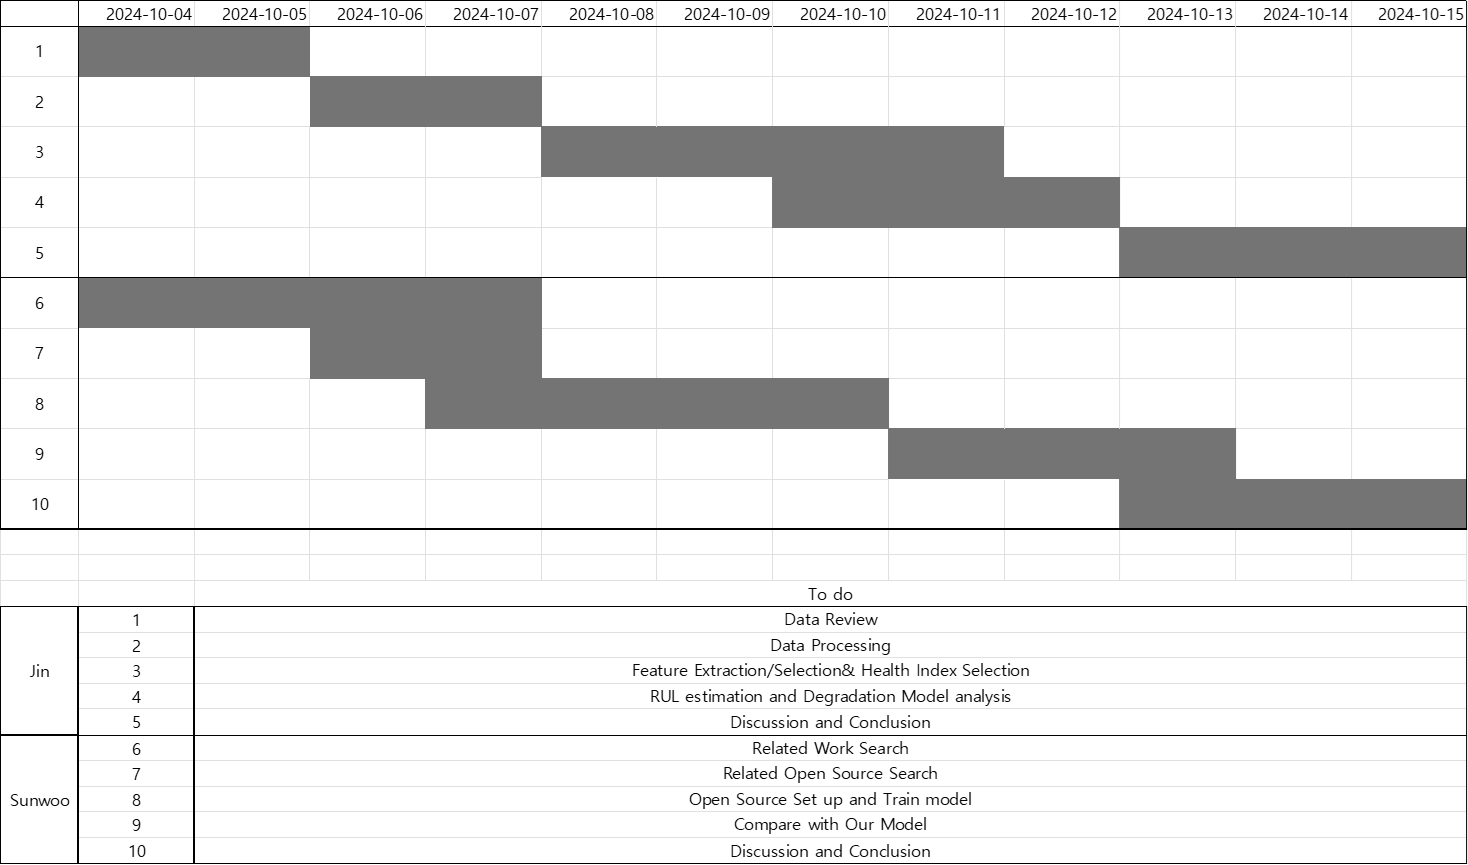

clc; clear all;
addpath("data\FAN_sound_error\");
addpath("data\FAN_sound_OK\")   ;
addpath("data\5공정_180sec\")   ;

**Import Sound Data **

N_sound_error = 13                               ;
N_sound_normal= 170                              ;
error_sound_filename  = "FAN_sound_error_0%d.wav";
normal_sound_filename = "FAN_sound_0%d.wav"      ;
for idx = 1:9
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end
error_sound_filename = "FAN_sound_error_%d.wav"  ;
normal_sound_filename= "FAN_sound_%d.wav"        ;
for idx = 10:13
    filename = sprintf(error_sound_filename,idx) ;
    [y,Fs] = audioread(filename)                 ;
    sound_error{idx,1} = y                       ;
    sound_error{idx,2} = Fs                      ;
end
for idx = 10:N_sound_normal
    filename = sprintf(normal_sound_filename,idx);
    [y,Fs] = audioread(filename)                 ;
    sound_normal{idx,1} = y                      ;
    sound_normal{idx,2} = Fs                     ;
end

**Import PLC data**

Unfortunately, the time-series data is not strictly real-time, in which means that this data is collected every 5 seconds approximately.

day   = [6:10,13:17,23,24,27:30,1,5:8,12:15,18:22,25:27];
month = [9*ones(1,16),10*ones(1,17)];
dates = datetime(2021,month,day,'Format','uuuu.MM.dd');
txt_form = "kemp-abh-sensor-%s.csv";
for idx = 1:length(day)
    file_name    = sprintf(txt_form,dates(idx));
    data_temp    = readmatrix(file_name) ; 
    plc_data{idx}= data_temp(:,[1,2,4,5]); 
end


**Data Enumeration**

Cell data will be in time-series and each features are grouped by a struct.

% Enumerations
IDX      = 1  ;
PROCESS  = 2  ;
TEMP     = 3  ;
CURRENT  = 4  ;
% For cell data
RAW_DATA = 1  ;
MAX_FREQ = 2  ;
FEAT     = 3  ;


**The sound data** is very similar to the vibration data as it has amplitude and frequency. Time and frequency features are to be extracted for the data analysis.

However, the sound data is subdivided into normal/error which means this should be only used as classification not RUL. Only possible if the sound data can be collected on real-time

for idx = 1 : N_sound_error
    sound_error{idx,3} = get_features(sound_error{idx,1});
end
for idx = 1 : N_sound_normal
    sound_normal{idx,3} = get_features(sound_normal{idx,1});
end

Compare time-domain sound data of normal/error

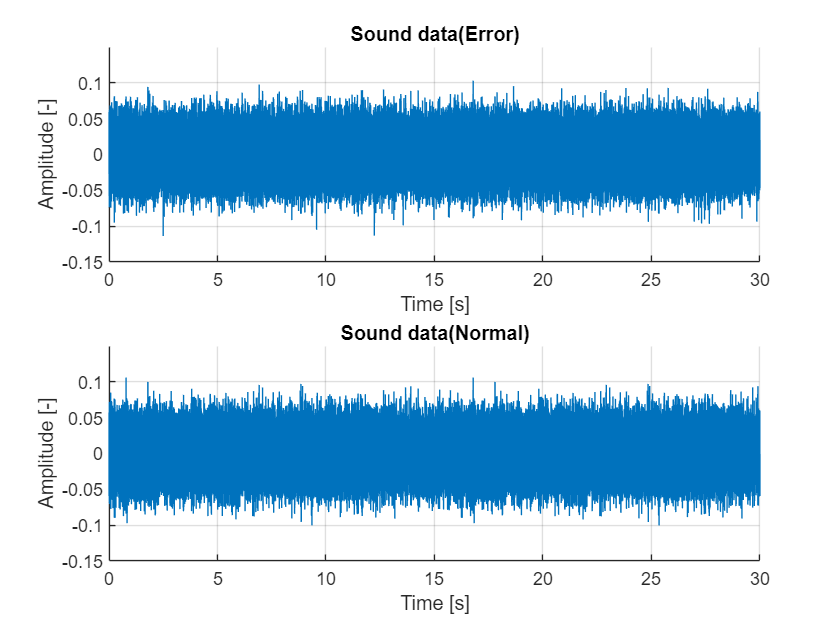

idx = 13;

ex_sound_error = sound_error {idx,RAW_DATA}(:,1);
ex_sound_normal= sound_normal{idx,RAW_DATA}(:,1);
time = 0:1/sound_error{idx,MAX_FREQ}:(length(ex_sound_error)-1)/Fs;

figure;
subplot(2,1,1); hold on;
title('Sound data(Error)','FontWeight','bold');
plot(time, ex_sound_error);grid on;
xlabel('Time [s]'); ylabel("Amplitude [-]");
time = 0:1/sound_normal{idx,MAX_FREQ}:(length(ex_sound_normal)-1)/Fs;
ylim([-0.15 0.15]);
subplot(2,1,2); hold on;
title('Sound data(Normal)','FontWeight','bold');
plot(time, ex_sound_normal); grid on;
xlabel('Time [s]'); ylabel("Amplitude [-]");
ylim([-0.15 0.15]);

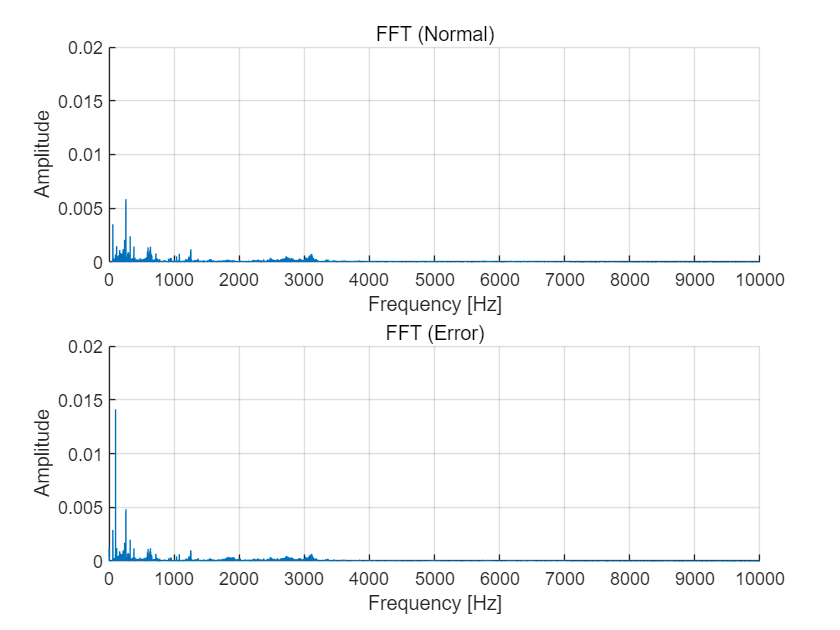

Fs = 44100;  %Hz
figure;
[freq, amp_normal] = get_fft(ex_sound_normal,Fs);
[freq, amp_error]  = get_fft(ex_sound_error,Fs);
figure;
subplot(2,1,1); hold on; grid on;
plot(freq,amp_normal); xlabel('Frequency [Hz]'); ylabel('Amplitude');
title('FFT (Normal)');ylim([0 0.02]); xlim([0 1e4]);
subplot(2,1,2); hold on; grid on;
plot(freq,amp_error); xlabel('Frequency [Hz]'); ylabel('Amplitude');
title('FFT (Error)');ylim([0 0.02]); xlim([0 1e4]);

To further illustrate the frequency features of normal/error data, `get_freq_features()` function is used.

normal_frequency_features = get_freq_features(amp_normal,Fs)

normal_frequency_features = 1×3 table
       max_amplitude       frequency_of_max_amplitude         DC_value      
    ___________________    __________________________    ___________________

    0.00583483055408493         518.599216025373         3.4779524975556e-07


error_frequency_features  = get_freq_features(amp_error,Fs)

error_frequency_features = 1×3 table
      max_amplitude       frequency_of_max_amplitude         DC_value      
    __________________    __________________________    ___________________

    0.0141144665900067         199.999697657298         0.00129010997684206


Each time features, frequency features are collected and averaged. They are plotted as below

First few sample data time features plot. This shows that error sound is very random and shows inconsistent values of all features.

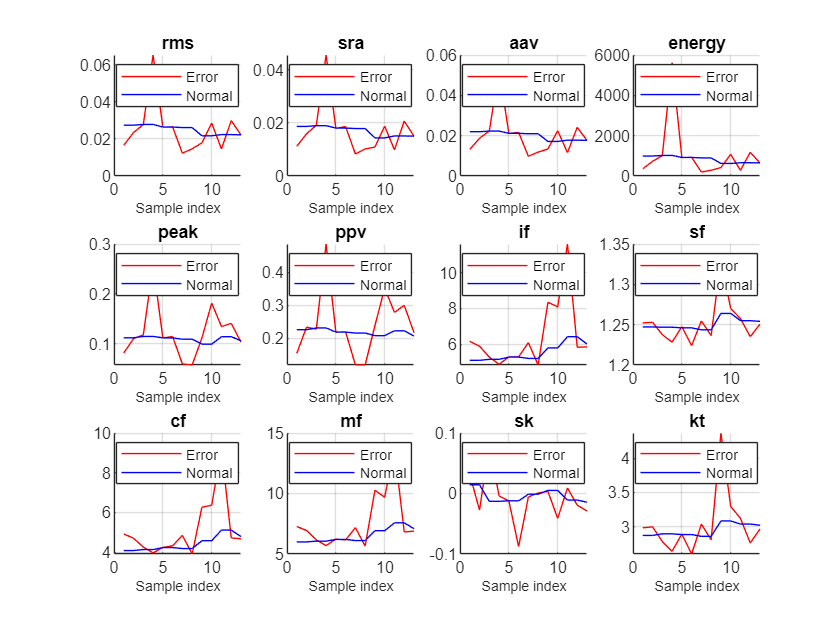

feature_names =["rms" "sra" "aav" "energy" "peak" "ppv" "if" "sf" "cf" "mf" "sk" "kt" "fft"];
figure;
for idx = 1:(length(feature_names)-1)
    avg(idx,1) = get_average_feature(sound_error ,feature_names(idx))       ;
    avg(idx,2) = get_average_feature(sound_normal,feature_names(idx))       ;
    error_features(:,idx)= get_all_feature(sound_error ,feature_names(idx)) ;
    normal_features(:,idx)= get_all_feature(sound_normal,feature_names(idx));
    subplot(3,4,idx); hold on; grid on           ;
    plot(error_features(:,idx),'r-')             ; 
    plot(normal_features(1:13,idx),'b-')         ;
    legend('Error','Normal')                     ;
    legend('Location','best')                    ;
    xlabel('Sample index','FontSize',7)          ;
    title(feature_names(idx),'FontWeight','bold');
end

# Data Preprocessing

## error data processing

% temperture / current 값에 대해서 error 별로 feature 뽑기
% PLC time-domain analysis

N_plc = 33;
Fs = 1.0 /5.0;
for idx = 1 : N_plc
    temp = plc_data {idx};
    plc_current{idx,1}  = temp(:,3);
    plc_current{idx,2}  = Fs;
    plc_current{idx,3}  = get_features(plc_current{idx,1});
    plc_temperature{idx,1}= temp(:,4);
    plc_temperature{idx,2}= Fs;
    plc_temperature{idx,3}= get_features(plc_temperature{idx,1});
end


error_list = readmatrix("Error Lot list.csv");
error_list = error_list(2:end,2:end);
if exist("var_names")
    clear var_names;
end
if exist("var_types")
    clear var_types;
end
for idx =1:length(error_list(1,:))
    var_names(idx) = sprintf("Error%d",idx);
end
var_names  = ["datetime" var_names];
error_names= var_names(2:end);

var_types(1,1:11) = "double";

var_types = ["datetime" var_types];
size_error_list =size(error_list);
size_error_list(2) = size_error_list(2)+1;
error_table= table('Size',size_error_list,'VariableTypes',var_types,'VariableNames',var_names);
error_table.datetime = dates';
for row = 1:length(error_list(:,1))
    for col = 1:length(error_list(1,:))
        if isnan(error_list(row,col))
            error_list(row,col) = 0;
        end
    end
end
error_table(:,2:end) = array2table(error_list);

% Sort by error
for row = 1:length(plc_data)
    temp_plc_data      = plc_data{row};
    temp_plc_data(:,5) = 0;
    for col= 1:length(error_list(1,:))
        if error_list(row,col) ~= 0
            indices = find(temp_plc_data(:,2) == error_list(row,col));
            temp_plc_data(indices,5) = col;
        end
    end
    plc_data{row} = temp_plc_data;
end

% Sort for RUL_Classification


# Feature extraction

% plc current data feature extraction

for idx_day = 1:33
    
    plc_data_day = plc_data{idx_day} ;
    process_col  = plc_data_day(:,2) ;
    cur_process  = process_col(1)    ;
    start_idx    = 1                 ;
    
    for idx_time = 2:length(plc_data_day)

        if cur_process ~= process_col(idx_time)
            end_idx = idx_time - 1 ;
            idx_feature = cur_process + (43 * (idx_day - 1));
            plc_current_feature(idx_feature) = get_features_error(plc_data_day(start_idx:end_idx,3), plc_data_day(start_idx:end_idx,5))     ;
            plc_temperature_feature(idx_feature) = get_features_error(plc_data_day(start_idx:end_idx,4), plc_data_day(start_idx:end_idx,5)) ;
            cur_process = process_col(idx_time) ;
            start_idx = idx_time ; 
        end

        if process_col(idx_time) == 43
            end_idx = length(plc_data_day) ;
            idx_feature = process_col(idx_time) + (43 * (idx_day - 1));
            plc_current_feature(idx_feature)     = get_features_error(plc_data_day(start_idx:end_idx,3), plc_data_day(start_idx:end_idx,5)) ;
            plc_temperature_feature(idx_feature) = get_features_error(plc_data_day(start_idx:end_idx,4), plc_data_day(start_idx:end_idx,5)) ;
        end
        
    end
   
end



train data 와 test data 나누기

N = length(plc_temperature_feature);
idx_train = 43 * 29; 

train_idx = 1;
test_idx  = 1;

for idx = 1:N

    if idx <= idx_train
        train_current(train_idx)     = plc_current_feature(idx);
        train_temperature(train_idx) = plc_temperature_feature(idx);
        train_idx = train_idx + 1;
    else
        test_current(test_idx)     = plc_current_feature(idx);
        test_temperature(test_idx) = plc_temperature_feature(idx);
        test_idx = test_idx + 1;
    end

end

# Feature Selection/Reduction

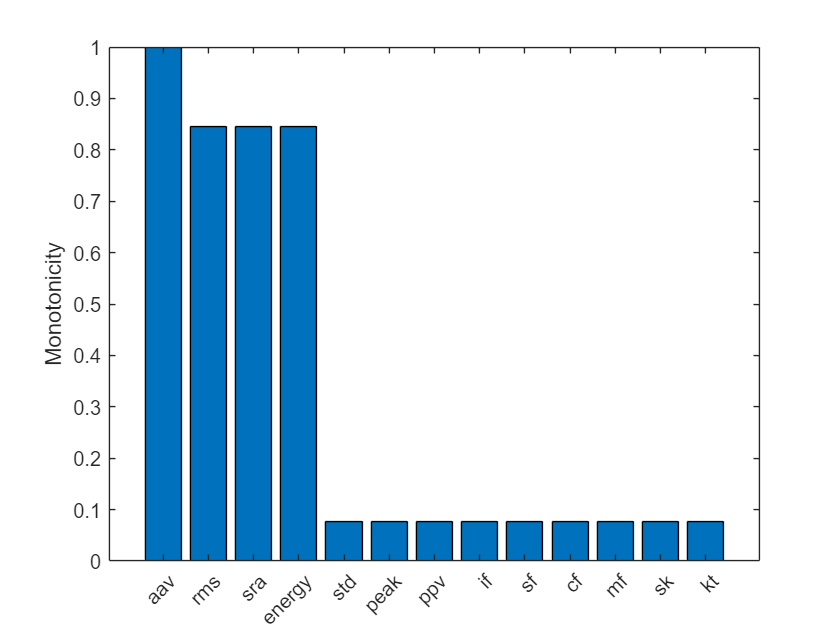

% error 별로 뽑은 feature 들을 feature selectoin 후 featuer reduction을 통해서 feature
% 정하기 temp / current 별로 구분
filed_c = struct2table(plc_current_feature(:,1:14));
filed_t = struct2table(plc_temperature_feature(:,1:14));
featureTable_current = filed_c(:,1:14);
featureTable_temperature = filed_t(:,1:14);
featureImportance_current = monotonicity(featureTable_current, 'WindowSize', 0);
helperSortedBarPlot(featureImportance_current, 'Monotonicity');

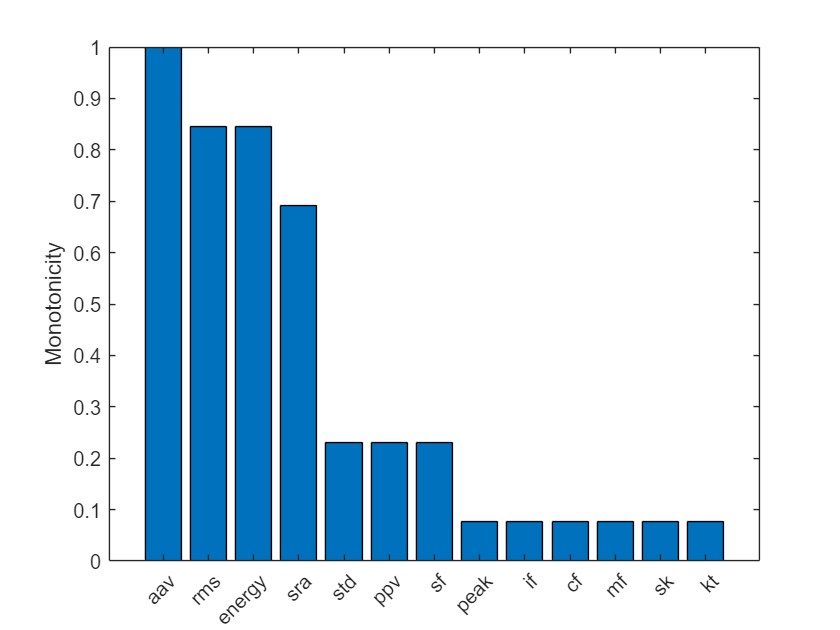

featureImportance_temperature = monotonicity(featureTable_temperature, 'WindowSize', 0);
helperSortedBarPlot(featureImportance_temperature, 'Monotonicity');

Top 4 important features selection

FI_c = featureImportance_current{:,:} > 0.3;
FI_t = featureImportance_temperature{:,:} > 0.3;
trainData_current     = struct2table(train_current);
trainData_temperature = struct2table(train_temperature);
trainDataSelected_current     = trainData_current(:, FI_c)

trainDataSelected_current = 1247×4 table
          std                 rms                 sra                 aav       
    ________________    ________________    ________________    ________________

    3.34320115461968    71.0311294935523    70.9166931915602    70.9545969985313
    3.30283865228561    71.0738772715173    70.9620507884587    70.9992275161293
    3.56530070260064    70.6669852304023    70.5359857584263    70.5794908315443
    3.09869669041235    71.2709746082266    71.1728376756865    71.2054535865061
    3.94251988868308     71.231232777711    71.0728909846749    71.1250787192739
    3.72545957492689    70.5093688297876    70.3655014908476    70.4136178084235
    3.23798673881698    70.8454726468465    70.7373658470351    70.7734955626744
    3.47509034785749    71.1208548142032    70.9972632304589    71.0382656604689
    2.98377838232004    70.9060032473438    70.8140506244524      70.84494101052
    3.30537099930834    70.8579212348689    70.7453467980488    70.

trainDataSelected_temperature = trainData_temperature(:, FI_t)

trainDataSelected_temperature = 1247×4 table
           std                  rms                 sra                 aav       
    __________________    ________________    ________________    ________________

    0.0784256647685078    1.61020497972676    1.60742805028253    1.60834708363054
    0.0744472115098161    1.60956363996927    1.60705520613766    1.60788888888889
      0.07869662464273    1.60149206471132    1.59867720670346    1.59961111111111
    0.0802770346664954    1.61316174638704     1.6102512652064    1.61121861610599
      0.09447315576857    1.61223151357179    1.60823115017509    1.60953819394909
    0.0818505413000495    1.59859408717647     1.5955316707926    1.59655555555556
    0.0757929875821501    1.60185157933787    1.59922935349091    1.60010733291333
    0.0805728615855282    1.60954709964005    1.60661263782423    1.60758521170131
    0.0658690379368802    1.60642456682189    1.60444746342513    1.60511111111111
     0.073230859138472    1.6052359293539

# Classification

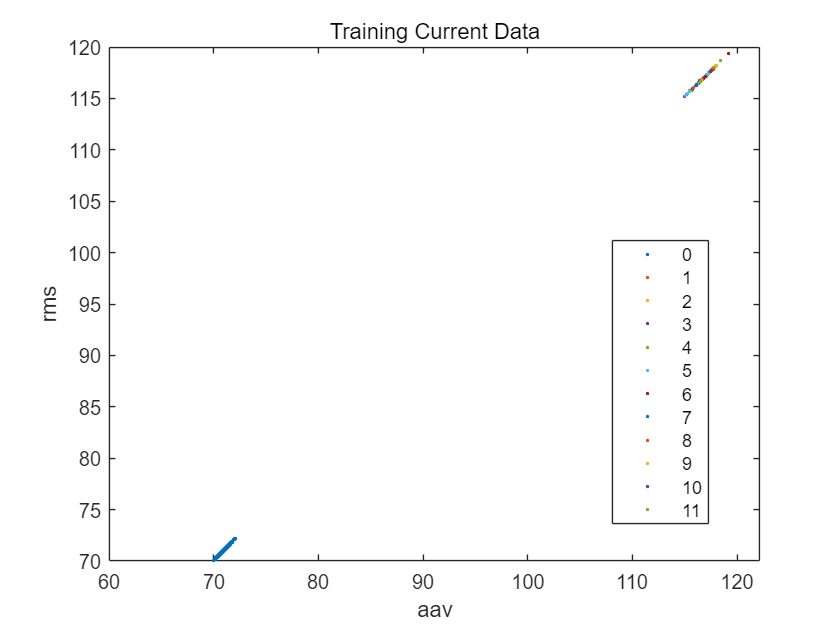

% current 와 temperature 의 feature selection을 진행한 traindata를 가지고 svm model
% 적용

% X : trainDataSelected_current Y : plc_current_feature(1:idx_train).error
X(:,1) = table2array( trainDataSelected_current(:,"aav") );
X(:,2) = table2array(trainDataSelected_current(:,"rms"));
X(:,3) = table2array(trainDataSelected_current(:,"sra"));
X(:,4) = table2array(trainDataSelected_current(:,"std"));

feature2table = struct2table(plc_current_feature(1:idx_train));
Y = table2array(feature2table(:,"error"));

figure;
gscatter(X(:, 1), X(:, 2),Y);
xlabel('aav');
ylabel('rms');
title('Training Current Data');
legend("Position",[0.72798,0.16845,0.11607,0.45119])

classLabels = categorical([0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11]);

% SVM 기반 ECOC 학습
cl = fitcecoc(X, Y, 'Learners', templateSVM('KernelFunction', 'rbf'), ...
              'ClassNames', classLabels, 'Coding', 'onevsall', 'Verbose', 1);

105개의 음성 관측값과 1142개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 1(SVM)을(를) 훈련시키는 중입니다.
1225개의 음성 관측값과 22개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 2(SVM)을(를) 훈련시키는 중입니다.
1225개의 음성 관측값과 22개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 3(SVM)을(를) 훈련시키는 중입니다.
1227개의 음성 관측값과 20개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 4(SVM)을(를) 훈련시키는 중입니다.
1235개의 음성 관측값과 12개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 5(SVM)을(를) 훈련시키는 중입니다.
1236개의 음성 관측값과 11개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 6(SVM)을(를) 훈련시키는 중입니다.
1239개의 음성 관측값과 8개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 7(SVM)을(를) 훈련시키는 중입니다.
1244개의 음성 관측값과 3개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 8(SVM)을(를) 훈련시키는 중입니다.
1244개의 음성 관측값과 3개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 9(SVM)을(를) 훈련시키는 중입니다.
1245개의 음성 관측값과 2개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 10(SVM)을(를) 훈련시키는 중입니다.
1246개의 음성 관측값과 1개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 11(SVM)을(를) 훈련시키는 중입니다.
1246개의 음성 관측값과 1개의 양성 관측값을 사용하여 전체 12개 중에서 이진 학습기 12(SVM)을(를) 훈련시키는 중입니다.


mlResubErr = resubLoss(cl)

mlResubErr =         0.0336808340016035


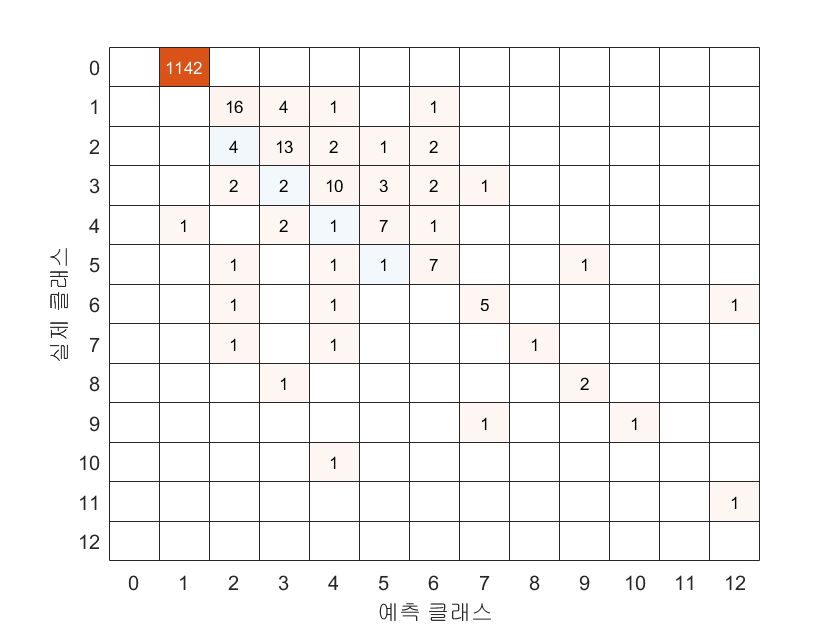

mlClass = resubPredict(cl);
mlClass_double = double(mlClass);
figure
ldaResubCM = confusionchart(Y,mlClass_double);

# Validation

# Fault Monitoring and Warning

# RUL Estimation

# Discussion

# Conclusion

**Functions**

function xfeature = get_features(x)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);

p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;
xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));
end

function xfeature = get_features_error(x,y)
% This is based on the function timeFeatures() 
% Input: Raw Data (Time-series)
% Output: Struct type
% |
% |---Time features(e.g. RMS, peak2peak, kurtosis)
% |---Frequency features(e.g. FFT, rmsf)
N = length(x);
N_Y= length(y);
xfeature.mean=mean(x);
xfeature.std=std(x);

xfeature.rms      =sqrt(sum(x.^2)/N);
xfeature.sra      =(sum(sqrt(abs(x)))/N).^2;
xfeature.aav      =sum(abs(x))/N;
xfeature.energy   =sum(x.^2);
xfeature.peak     =max(x);
xfeature.ppv      =peak2peak(x);
xfeature.if       =xfeature.peak/xfeature.aav;
xfeature.sf       =xfeature.rms/xfeature.aav;
xfeature.cf       =xfeature.peak/xfeature.rms;
xfeature.mf       =xfeature.peak/xfeature.sra;
xfeature.sk       =skewness(x);
xfeature.kt       =kurtosis(x);

p1 = fft(x);
p1(2:end-1)= 2.0 * p1(2:end-1); 
xfeature.fft = p1;
xfeature.rmsf= sqrt(1/N *sum(xfeature.fft.^2));

xfeature.error = sum(y)/N_Y;
end


%%

function average_feature = get_average_feature(x,feature_name)
% Input: the whole cell
    FEATURES =3;
    N = length(x);
    feature = 0.0;
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        feature = feature + val(1);
    end
    average_feature = feature/N;
end

%%
function vectors = get_all_feature(x,feature_name)
% Input: whole cell
    FEATURES =3;
    N = length(x);
    vectors = [];
    for idx= 1:N
        structure = x{idx,FEATURES};
        val =getfield(structure,feature_name);
        vectors = [vectors; val(1)]; 
    end
end

%%
function [frequency , Amplitude] = get_fft(data,Fs)
% Input : data: Time-series data
%         Fs  : Sampling Frequency
% Output: frequency: Frequency Domain(Bound)
%         Amplitude: Corresponding amplitude of fft data to the frequency
    N = length(data);
    frequency = 0.0:Fs/N:Fs/2;
    fft_data = abs(fft(data)/N);
    fft_data = fft_data(1:floor(N/2)+1);
    fft_data(2:end-1) = 2*fft_data(2:end-1);
    Amplitude = fft_data;
end

%%
function frequency_features = get_freq_features(fft_data, Fs)
% Input  fft_data: fft amplitude data
%        Fs: sampling frequency
% Output frequency_features: table for frequency features. 
    N = length(fft_data);
    frequency_features = table;
    frequency_features.max_amplitude     = max(fft_data);
    frequency_features.frequency_of_max_amplitude = (find(fft_data == max(fft_data))-1)*Fs/N;
    frequency_features.DC_value = fft_data(1);
end
%%



## Reference

[1] (주) KEMP, *Innozinc**세라믹 아연도금**,* [http://kempkorea.com/](http://kempkorea.com/) 

[2] Rauber, Thomas W., Francisco de Assis Boldt, and Flavio Miguel Varejao. "Heterogeneous feature models and feature selection applied to bearing fault diagnosis." *IEEE Transactions on Industrial Electronics* 62.1 (2014): 637-646.

[3] Toliyat, Hamid A., et al. *Electric machines: modeling, condition monitoring, and fault diagnosis*. CRC press, 2017.

[4] 